# MPC Algorithm for pendulum swing up

## Setting the path

addpath("../Model/"); % NL equations
addpath("../optimization/UncOpt/"); % optimization routines
addpath("../optimization/ConsOpt/");
addpath("../Manual_Validation/esp/theta_esp/"); % experimental data
addpath("../Manual_Validation/esp/alpha_esp/");
addpath("../Manual_Validation/esp/theta_d_esp/");
addpath("../Manual_Validation/esp/alpha_d_esp/");
addpath("../Manual_Validation/esp/t_esp/");
addpath("../Manual_Validation/esp/voltage_esp/");
addpath("../SYSID/");
addpath("../")

### Model Parameters from datasheet

To add loading of identified parameters as option

startUp % load datasheet model parameter values
load('th_id.mat')
th = id_param;

## Control Problem Parameters

maybe increase the time horizon

%% Control problem parameters
Ts          =   0.002;              % Sampling time
z0          =   [0;pi;0;0];         % Initial state
Q           =   diag([1;2;1;1]);    % Tracking error weight
Qf          =   1e3;                % Terminal weight
R           =   2;                  % Input weight
Tend        =   3;                  % Time horizon
N           =   Tend/Ts;            % Prediction steps
usat        =   6;                  % Input saturation
xsat        =   .8;                 % Cart position limits
alpha       =   1e-5;               % Barrier function scaling
beta        =   10;                 % Barrier function coefficient

U0 = 0.1*ones(N,1);

### Precdompiled Files 

Run these commands if you change any of the parameters above

%codegen Pendulum_cost_constr_GN -args {U0,z0,Ts,Q,R,usat,xsat,alpha,beta,Qf,th}
%codegen Pendulum_cost_constr -args {U0,z0,Ts,Q,R,Qf,usat,xsat,alpha,beta,th}

## Optimization routine parameters

% Initialize solver options
myoptions   =   myoptimset;
myoptions.ls_beta       = 0.3;        
myoptions.ls_c          = 0.1;
myoptions.gradmethod    = 'FD';
myoptions.graddx        = eps^(1/3);
myoptions.nitermax      = 5e2;
myoptions.Hessmethod    = 'GN';
%myoptions.GN_funF       = @(U)Pendulum_cost_constr_GN(U,z0,Ts,Q,R,Qf,usat,xsat,alpha,beta,th);
myoptions.GN_funF       = @(U)Pendulum_cost_constr_GN_mex(U,z0,Ts,Q,R,Qf,usat,xsat,alpha,beta,th);

### Initial guess

here we define the initial guess for the input voltage

%% Running the optimization routine
%[Ustar,fxstar,k,exitflag,xsequence] = myfminunc(@(U)Pendulum_cost_constr(U,z0,Ts,Q,R,Qf,usat,xsat,alpha,beta,th),U0,myoptions);
[Ustar,fxstar,k,exitflag,xsequence] = myfminunc(@(U)Pendulum_cost_constr_mex(U,z0,Ts,Q,R,Qf,usat,xsat,alpha,beta,th),U0,myoptions);

Iteration       NormGrad          Cost      Rel. cost         Rel. x      Line-search
        0    2.00169e+07   1.01075e+07    1.00000e+00    1.00000e+00                0
        1    1.30743e+07   6.63338e+06    3.43715e-01    6.04607e+00                1
        2    1.17132e+07   5.95363e+06    1.02475e-01    2.45591e-01                2
        3    1.06522e+07   5.42650e+06    8.85388e-02    2.01485e-01                2
        4    9.86622e+06   5.03887e+06    7.14332e-02    1.77626e-01                2
        5    9.38070e+06   4.80162e+06    4.70828e-02    1.66862e-01                2
        6    9.00568e+06   4.61494e+06    3.88799e-02    4.94861e-02                3
        7    8.65320e+06   4.43924e+06    3.80718e-02    4.95498e-02                3
        8    8.32179e+06   4.27374e+06    3.72801e-02    4.96794e-02                3
        9    8.00979e+06   4.11759e+06    3.65383e-02    4.98399e-02                3
       10    7.71539e+06   3.96984e+06    3.58831e-02 

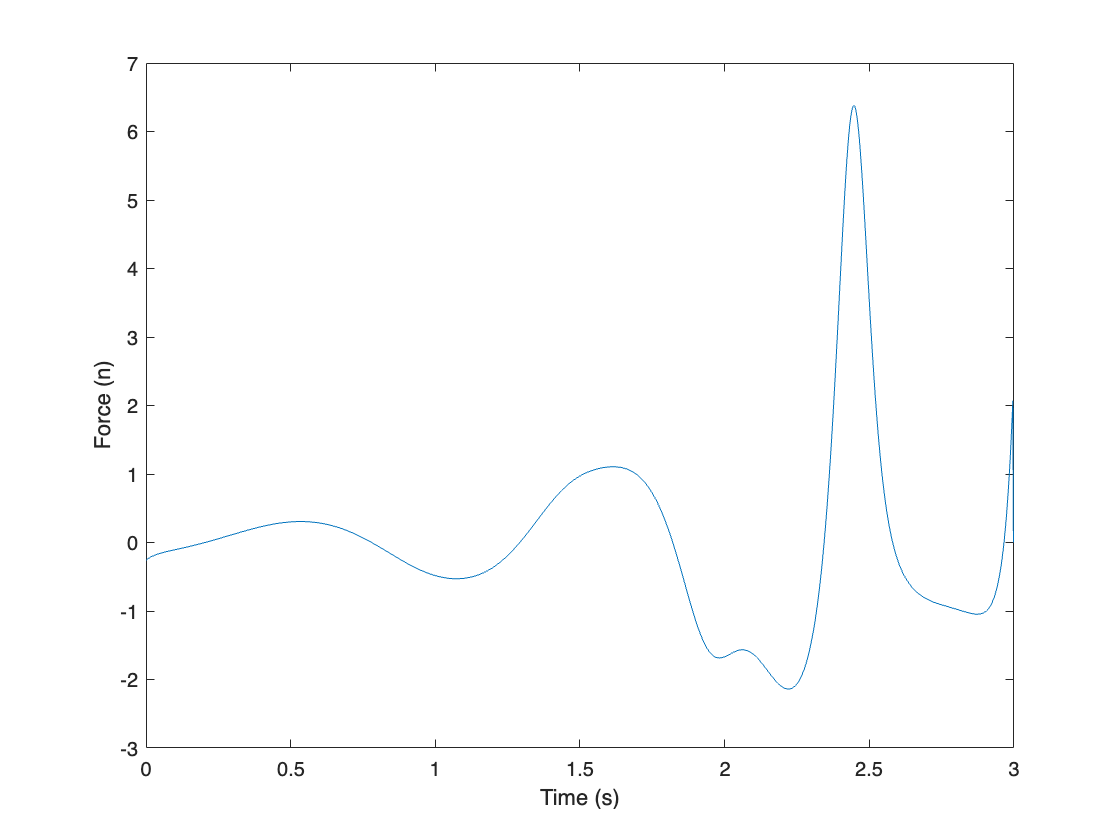


%% Post-processing the results
%[fstar,zstar] = Pendulum_cost_constr(Ustar,z0,Ts,Q,R,Qf,usat,xsat,alpha,beta,th);
[fstar,zstar] = Pendulum_cost_constr_mex(Ustar,z0,Ts,Q,R,Qf,usat,xsat,alpha,beta,th);

figure,plot(0:Ts:(N-1)*Ts,Ustar),xlabel('Time (s)'),ylabel('Force (n)')

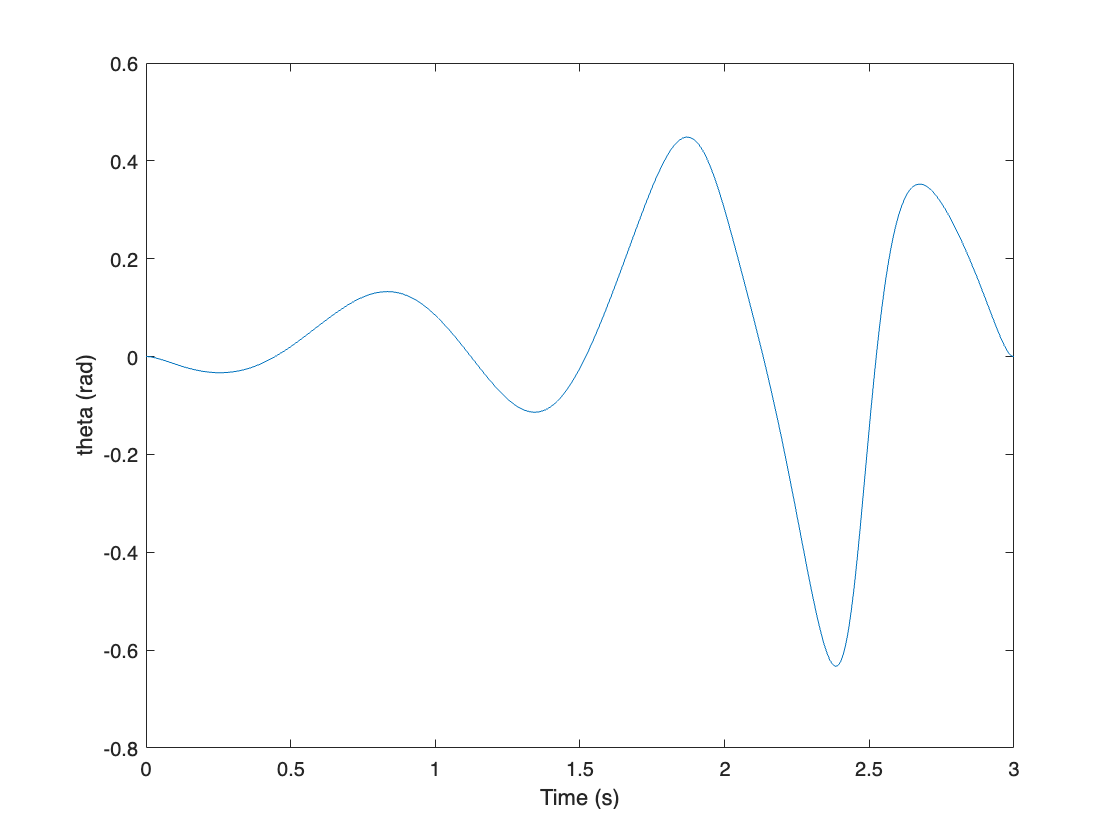

figure,plot(0:Ts:N*Ts,zstar(1:4:end,1)),xlabel('Time (s)'),ylabel('theta (rad)')

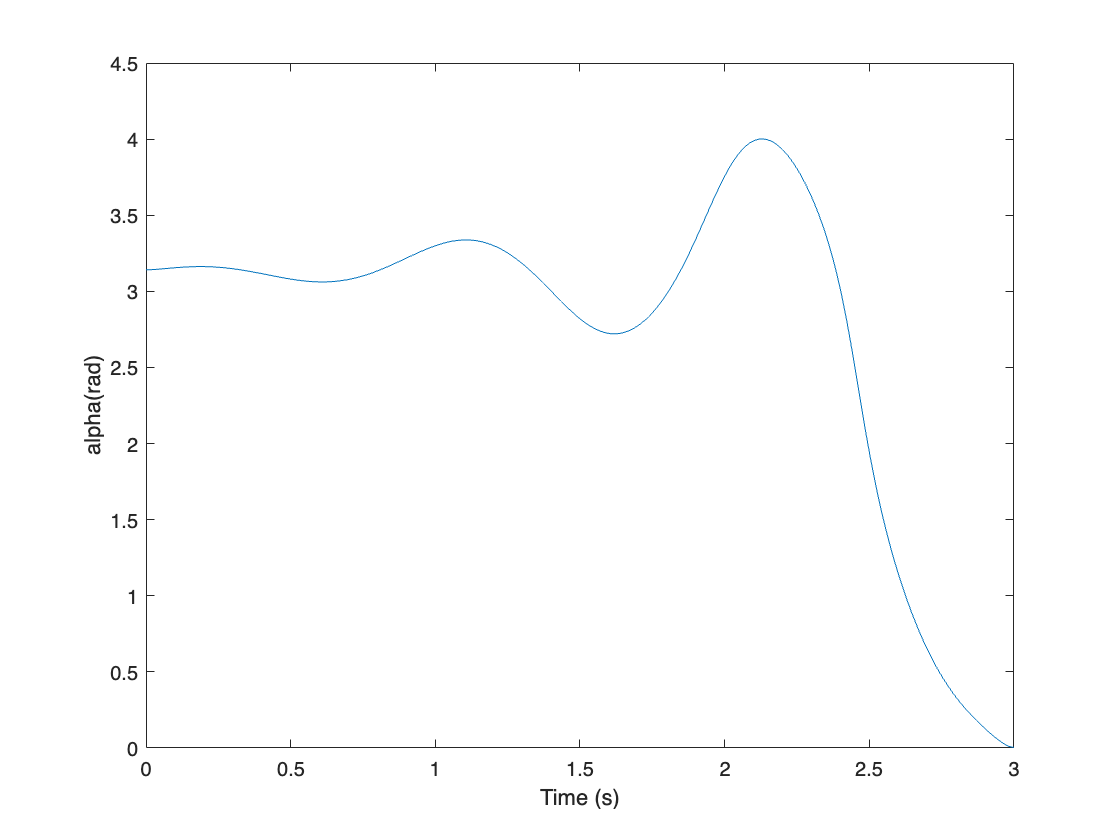

figure,plot(0:Ts:N*Ts,zstar(2:4:end,1)),xlabel('Time (s)'),ylabel('alpha(rad)')